Assume:

Va=1m/s

Startup=2s

a=0.5m/s^2

straight line movement 1s

arc movement 0.5s R=4m

straight line movement 0.5s

deceleration stop 2s

V(t)= 0.5t for t={0,2}

V(t)= 1 for t={2,2+1+0.5+0.5+2}

0.5(2+1+0.5+0.5+2) = 3

V(t) = -0.5t + 3 for t={4,6}

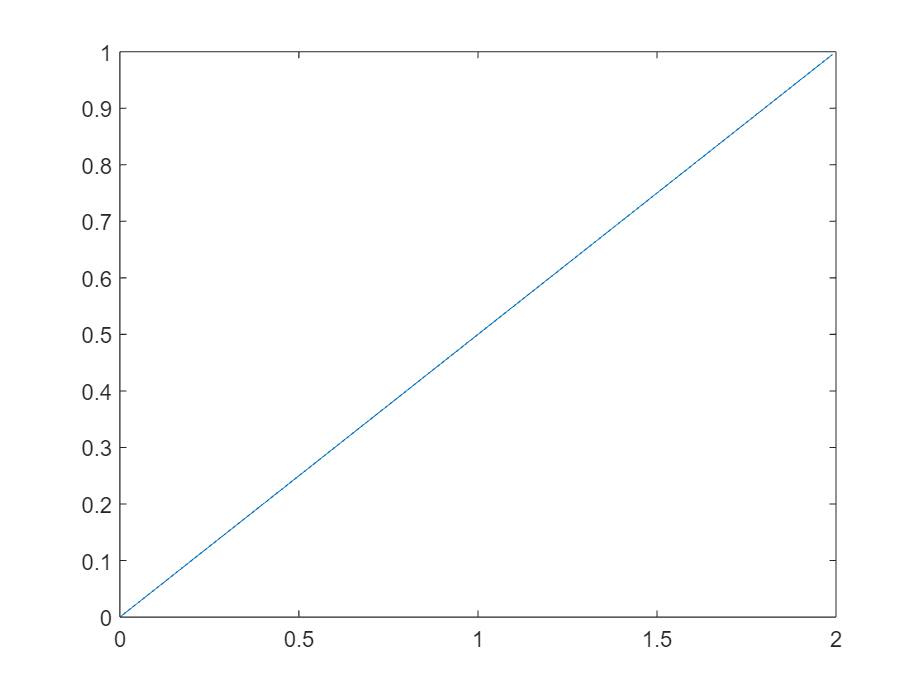

fs=100;
dt=1/fs;
t=0:dt:6-dt;
Va=0.5*t(1:(2*fs));
plot(t(1:(2*fs)),Va)

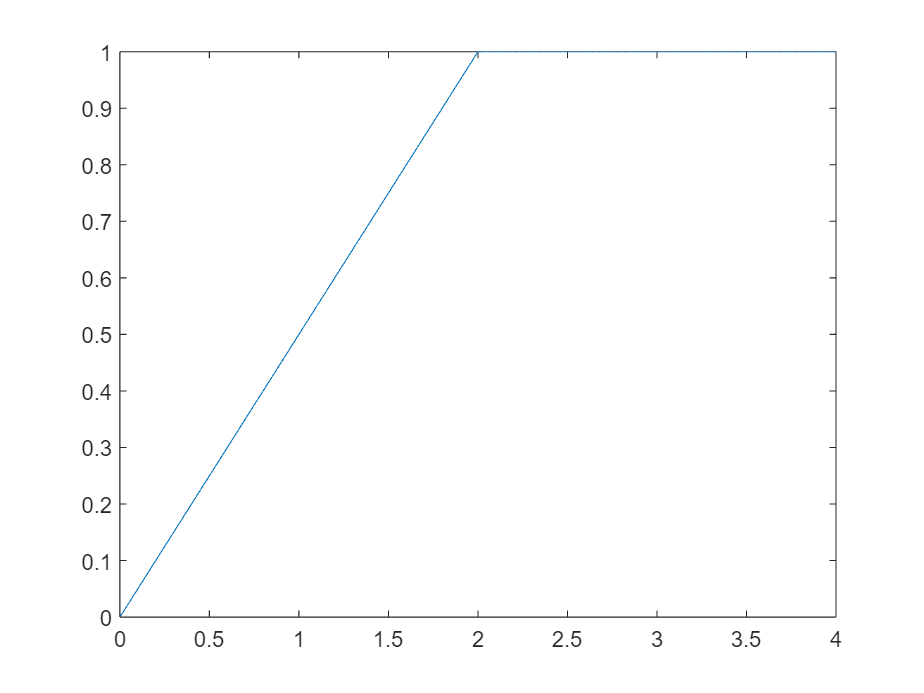


Va=[Va,ones(1,2*fs)];
plot(t(1:(4*fs)),Va)

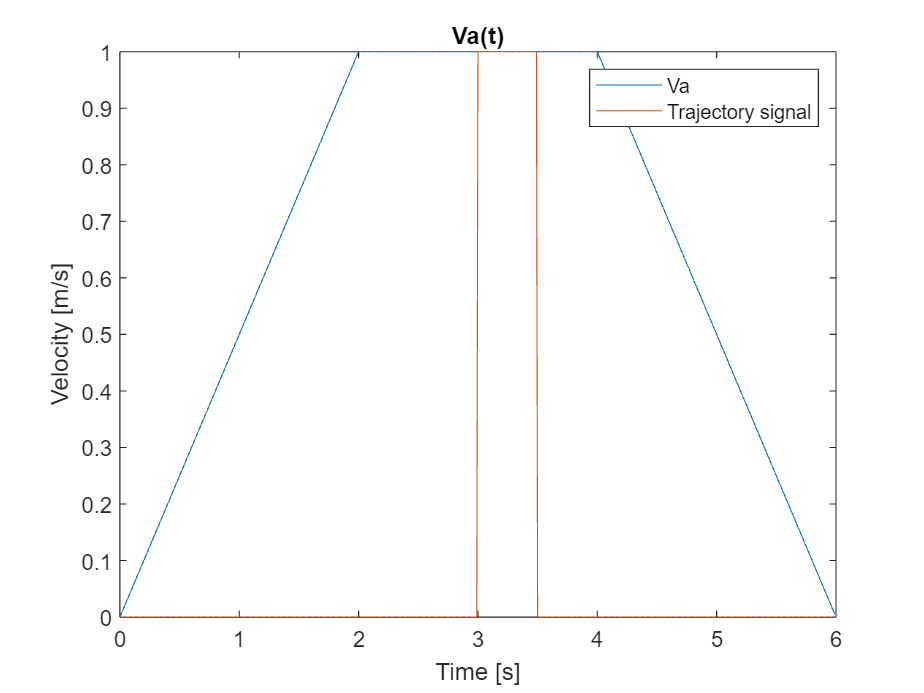


Va=[Va,-0.5*t(4*fs+1:6*fs)+3];
plot(t,Va);hold on
title('Va(t)')
xlabel('Time [s]')
ylabel('Velocity [m/s]')

trajSig=[zeros(1,3*fs),ones(1,0.5*fs),zeros(1,2.5*fs)];
plot(t,trajSig);hold off
legend('Va','Trajectory signal')

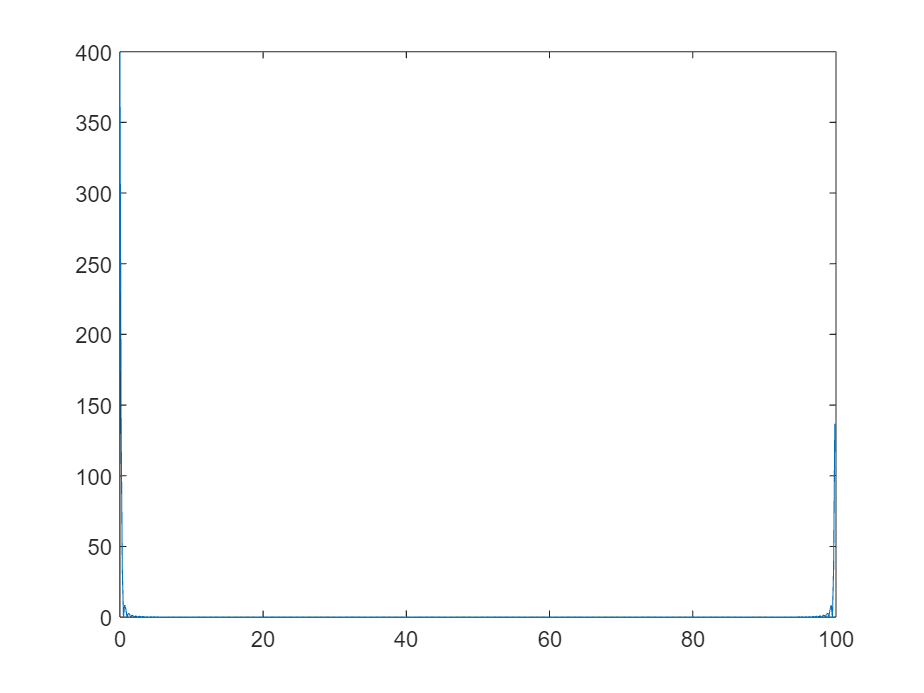

N=length(t);
df=fs/N;
fv = (0:N-1)*df; % frequency vector

plot(fv,abs(fft(Va)))


[Vas,group_delay] = FilterData([Va,zeros(1,0.3*fs)])

Vas =          0   -0.0000   -0.0000   -0.0000   -0.0001   -0.0002   -0.0003   -0.0004   -0.0004   -0.0001    0.0005    0.0017    0.0035    0.0060    0.0092    0.0130    0.0174    0.0221    0.0271    0.0322    0.0373    0.0424    0.0474    0.0525    0.0575    0.0625    0.0675    0.0725    0.0775    0.0825    0.0875    0.0925    0.0975    0.1025    0.1075    0.1125    0.1175    0.1225    0.1274    0.1324    0.1374    0.1424    0.1474    0.1524    0.1574    0.1624    0.1674    0.1724    0.1774    0.1824


group_delay = 12

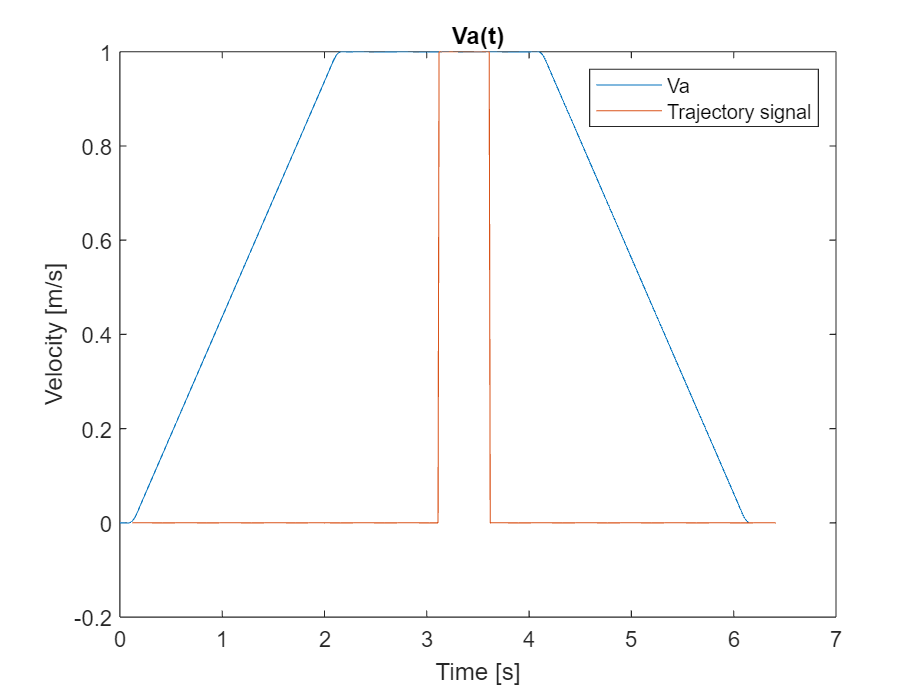

t2=0:dt:6-dt+0.3;
plot(t2,Vas);hold on
title('Va(t)')
xlabel('Time [s]')
ylabel('Velocity [m/s]')
plot(t2+group_delay*dt,[trajSig,zeros(1,30)]);hold off
legend('Va','Trajectory signal')

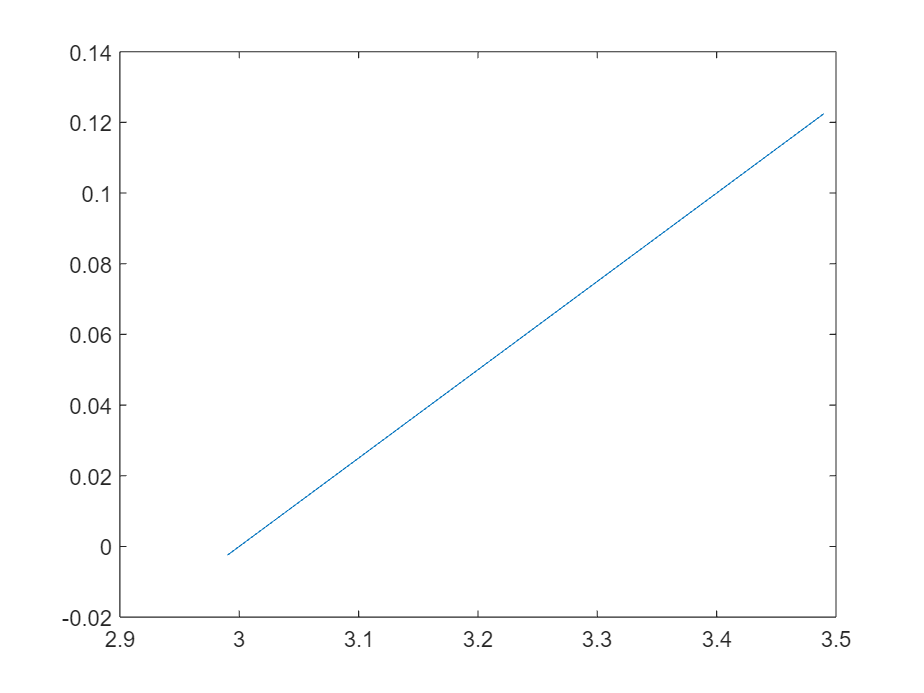

%arc len s=v*t
s=1*0.5; %[m/s * s]
r=4; %[m]
d_ang_tot=s/r; %[rad]
d_ang_t=[zeros(1,fs*3),d_ang_tot*2*t(fs*3+1:fs*3.5)-0.75,d_ang_tot*ones(1,fs*2.5)];

plot(t(fs*3:fs*3.5),d_ang_tot*2*t(fs*3:fs*3.5)-0.75)

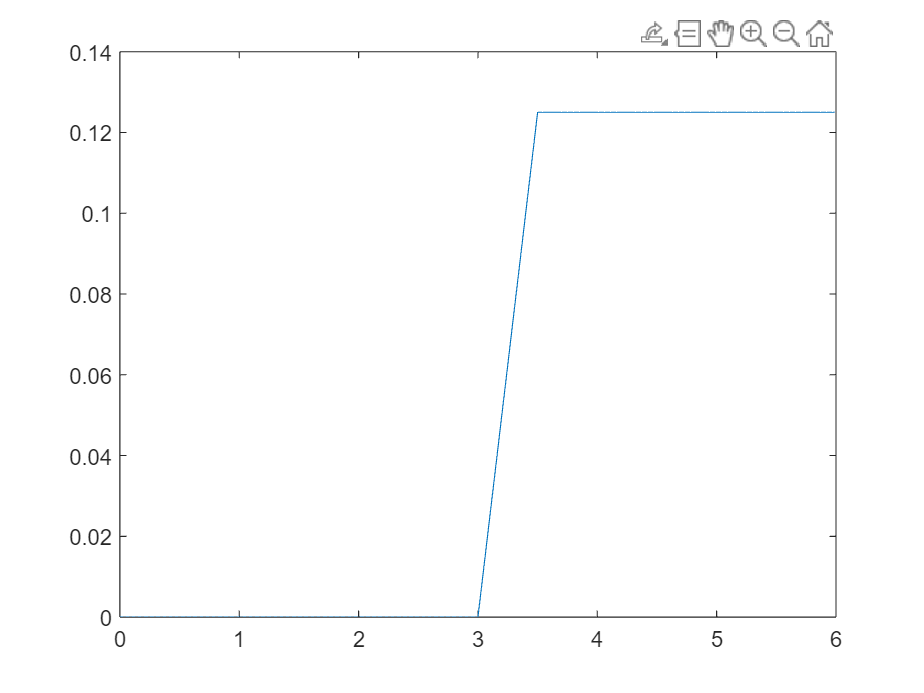

plot(t,d_ang_t)

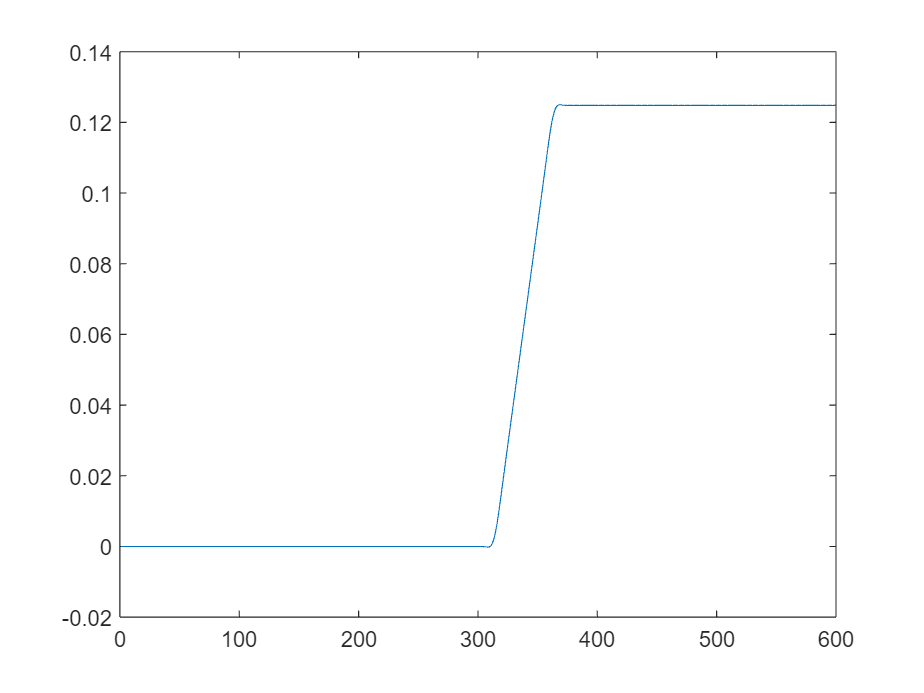

[d_ang_ts,group_delay2] = FilterData(d_ang_t);
plot(d_ang_ts)

function [dataFiltered,group_delay] = FilterData(data)

[n,m]=size(data);

%Forcing row vectros
if n>m
    data=data';
    n=temp;
    n=m;
    m=temp;
end

%Init Filter
Hd=filterF;

%Filtering and scaling all signals one by one
for i=1:n
    
%Applying filter
x=Hd.filter(data(i,:));

%Scaling the filtered signal 
group_delay = floor((length(Hd.Numerator) - 1)/2);
% x = x(group_delay+1:end);

scale_factor = max(data(i,:)) / max(x);
x = x * scale_factor;

%Appending Filtered and scaled signal
dataFiltered(i,:)=x;
end
end


function Hd = filterF
%FILTERF Returns a discrete-time filter object.

% MATLAB Code
% Generated by MATLAB(R) 9.14 and Signal Processing Toolbox 9.2.
% Generated on: 25-Mar-2024 10:36:58

% Equiripple Lowpass filter designed using the FIRPM function.

% All frequency values are in Hz.
Fs = 100;  % Sampling Frequency

Fpass = 5;            % Passband Frequency
Fstop = 15;           % Stopband Frequency
Dpass = 0.057501127785;  % Passband Ripple
Dstop = 0.0001;          % Stopband Attenuation
dens  = 20;              % Density Factor

% Calculate the order from the parameters using FIRPMORD.
[N, Fo, Ao, W] = firpmord([Fpass, Fstop]/(Fs/2), [1 0], [Dpass, Dstop]);


% Calculate the coefficients using the FIRPM function.
b  = firpm(N, Fo, Ao, W, {dens});
Hd = dfilt.dffir(b);

end
